## Signals and Systems - CA3 - Mohammad Farrahi

## Stud. Num. : 810198451

### Conceptual Questions

1 -

پردازش سیگنال ها در کامپیوتر به صورت گسسته انجام می گیرد. برای همین در تبدیل فوریه گرفتن از سیگنال آنالوگ در متلب، باید ابتدا از آن سیگنال نمونه برداری کنیم. اگر فرکانس نمونه برداری $f_s$  باشد و $N$  نمونه از سیگنال اصلی حاصل شده باشد، با دادن این $N$ نمونه (که یک سیگنال گسسته با سایز $N$ هست) به تابع $fft$ متلب، تبدیل فوریه سیگنال اصلی گسسته-زمان را از $fft$ دریافت می کنیم . سیگنال خروجی که سایز آن $N$است، نشان دهنده $N$ضربه در بازه $[0,2\pi]$است. در حقیقت $fft$ از سیگنال ورودی، یک سیگنال متناوب با دوره تناوب $N$ می سازد و سری فوریه سیگنال جدید را محاسبه می کند. برای تناظر دادن مقادیر خروجی به محور فرکانس$(f)$ (بعد از اعمال $fftshift$برای متقارن کردن نسبت فرکانس 0،  محور افقی را$-\frac{f_s }{2}:\frac{f_s }{N}:\frac{f_s }{2}-\frac{f_s }{N}$  در نظر می گیریم ( طبق قانون $Nyquist
$ )

2 - As mentioned at end of problem description section, frequency resolution is equal to $f_s / N$. Since $f_s$ is equat to $1/t_s$ , we have :


$$\frac{f_s }{N}=\frac{1}{t_s \times N}=\frac{1}{T}$$


Based on equation above, we can see that frequncy resolution is equal to revese of duration of data(T) and independent of sampling frequency

### Spectral Response

#### x1(t)

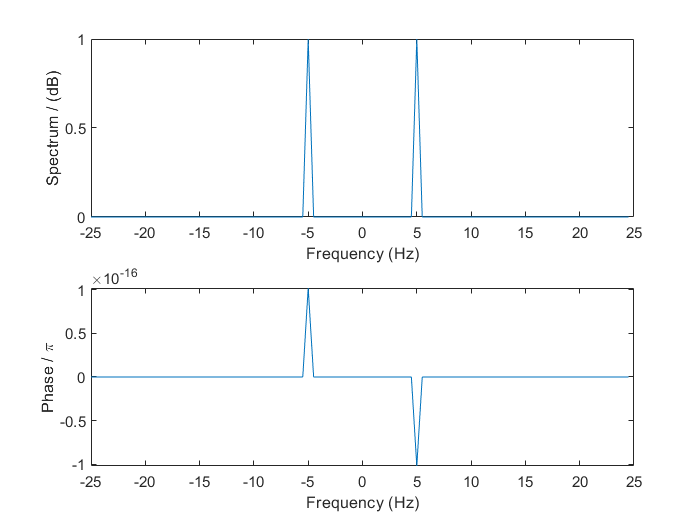

tstart = -1;
tend = 1;
fs = 50;

ts = 1/fs;
t = tstart:ts:tend-ts;
N = length(t);
x1 = cos(10*pi*t);

tol = 1e-10;
f = -fs/2:fs/N:fs/2 - fs/N;
xhat = fftshift(fft(x1));
xhat = xhat / max(abs(xhat));
xhat(abs(xhat) < tol) = 0;

subplot(2,1,1)
plot(f, abs(xhat))
xlabel('Frequency (Hz)')
ylabel('Spectrum / (dB)')

subplot(2,1,2)
plot(f, angle(xhat) / pi)
xlabel('Frequency (Hz)')
ylabel('Phase / \pi')

theoretical fourier transform:


$$\cos \left(10\pi \;t\right)\longrightarrow \pi \;\delta \left(w-10\pi \right)+\pi \;\delta \left(w+10\pi \right)$$


Which in scale of Frequncy, we have two impulse in frequencies of $\pm 5\;\left(w=2\pi f\right)$with phase of zero. we can see nearly same result as we expected. ( value of phase on +5 , -5 is too small, about 10^(-16) )

Noting that we approximated the fft values with absolute of less than 10^(-5) to zero

#### x2(t)

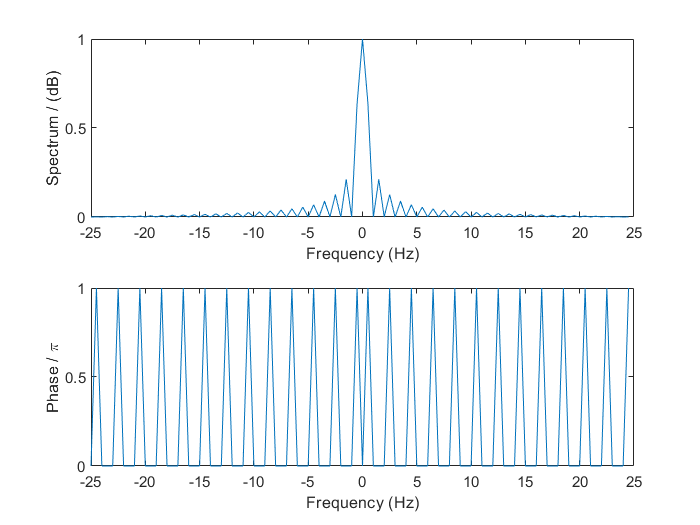

tstart = -1;
tend = 1;
fs = 50;

ts = 1/fs;
t = tstart:ts:tend-ts;
N = length(t);
x2 = rectangularPulse(t);


tol = 1e-12;
f = -fs/2:fs/N:fs/2 - fs/N;
xhat = fftshift(fft(x2));
xhat = xhat / max(abs(xhat));
xhat(abs(xhat) < tol) = 0;
xhat(imag(xhat) < tol) = real(xhat(imag(xhat) < tol));

subplot(2,1,1)
plot(f, abs(xhat))
xlabel('Frequency (Hz)')
ylabel('Spectrum / (dB)')

subplot(2,1,2)
plot(f, angle(xhat)/pi)
xlabel('Frequency (Hz)')
ylabel('Phase / \pi')

theoretical fourier transform:


$$\Pi \left(t\right)\longrightarrow \mathrm{sinc}\left(\frac{w}{2\pi }\right)=\mathrm{sinc}\left(f\right)\;$$


Since we are plotting absolute values, the result is as same as expected.

Also, because angle of real negative values is $\pi$, and sinc(f) is negative at some frequencies, we have angle of $\pi
$ at some frequencies 

Noting that we approximated the fft values with absolute of less than 10^(-12) to zero and vlues with imaginary part of less than 10^(-12) to real part of themselves.

#### x3(t)

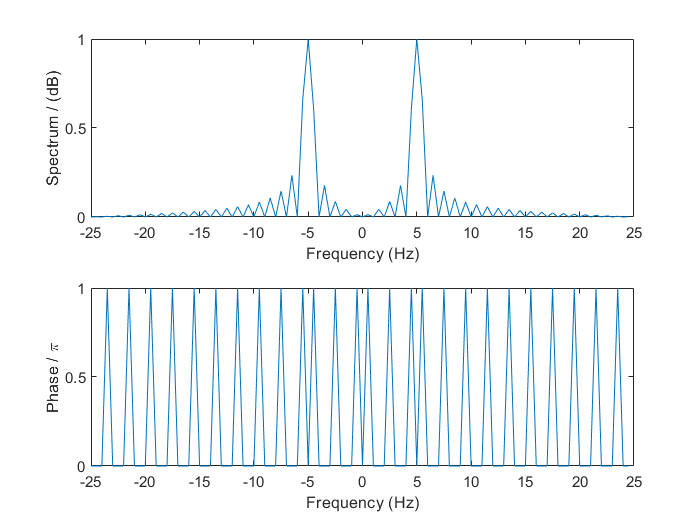

tstart = -1;
tend = 1;
fs = 50;

ts = 1/fs;
t = tstart:ts:tend-ts;
N = length(t);
x3 = rectangularPulse(t) .* cos(10*pi*t);


tol = 1e-12;
f = -fs/2:fs/N:fs/2 - fs/N;
xhat = fftshift(fft(x3));
xhat = xhat / max(abs(xhat));
xhat(abs(xhat) < tol) = 0;
xhat(imag(xhat) < tol) = real(xhat(imag(xhat) < tol));

subplot(2,1,1)
plot(f, abs(xhat))
xlabel('Frequency (Hz)')
ylabel('Spectrum / (dB)')

subplot(2,1,2)
plot(f, angle(xhat)/pi)
xlabel('Frequency (Hz)')
ylabel('Phase / \pi')

theoretical fourier transform:


$$\cos \left(10\pi t\right)\times \Pi \left(t\right)\longrightarrow \left(\pi \;\delta \left(w-10\pi \right)+\pi \;\delta \left(w+10\pi \right)\right)*\left(\mathrm{sinc}\left(\frac{w}{2\pi }\right)\right)\;$$


Since if impulse function convolves with any function $f$, we would have shifted version of $f$, therefore we expect to see two shifted version of $\mathrm{sinc}$ function at frequencies of $\pm 5$hertz which what we see in plot.

#### x4(t)

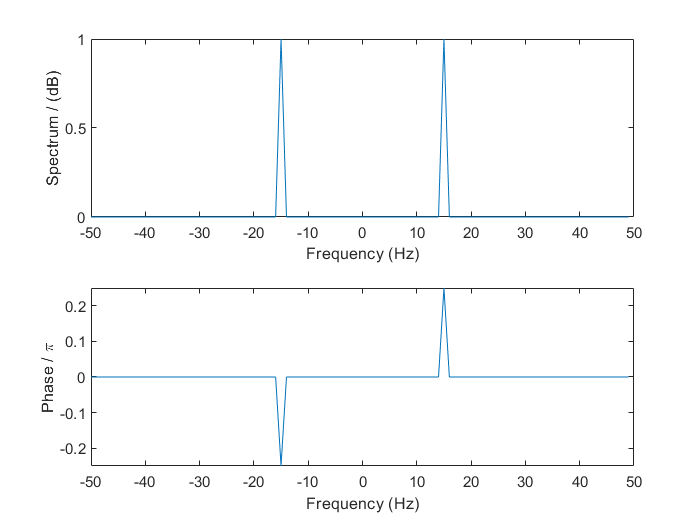

tstart = 0;
tend = 1;
fs = 100;

ts = 1/fs;
t = tstart:ts:tend-ts;
N = length(t);
x4 = cos(30*pi*t + pi/4);

tol = 1e-10;
f = -fs/2:fs/N:fs/2 - fs/N;
xhat = fftshift(fft(x4));
xhat = xhat / max(abs(xhat));
xhat(abs(xhat) < tol) = 0;

subplot(2,1,1)
plot(f, abs(xhat))
xlabel('Frequency (Hz)')
ylabel('Spectrum / (dB)')

subplot(2,1,2)
plot(f, angle(xhat) / pi)
xlabel('Frequency (Hz)')
ylabel('Phase / \pi')

theoretical fourier transform:


$$\cos \left(30\pi t+\frac{\pi }{4}\right)\longrightarrow \pi \;e^{\frac{\pi }{4}i} \delta \left(w-30\pi \right)+\pi \;e^{-\frac{\pi }{4}i} \delta \left(w+30\pi \right)$$


Which in scale of Frequncy, we have two impulse(dirac delta) in frequencies of $\pm 15\;\left(w=2\pi f\right)$with phase of $\pm \frac{\pi }{4}$. we can see nearly same result as we expected.

Noting that we approximated the fft values with absolute of less than 10^(-5) to zero

#### x5(t)

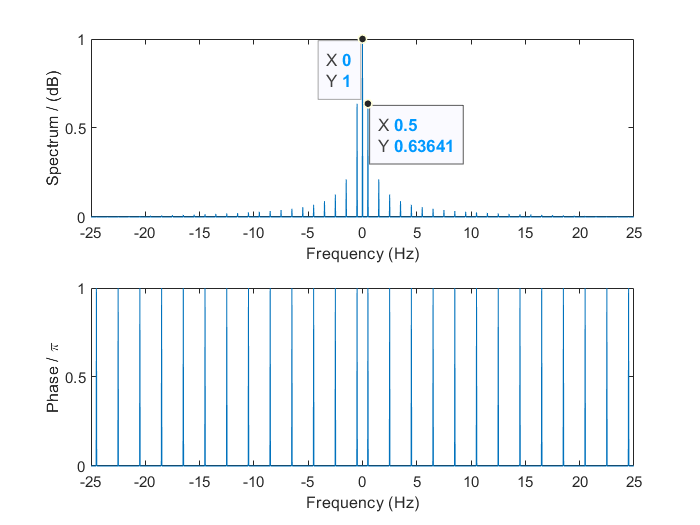

tstart = -19;
tend = 19;

fs = 50;

ts = 1/fs;
t = tstart:ts:tend-ts;
N = length(t);

x5 = zeros(1, N);
for k = 0:9
    temp = rectangularPulse(t - 2*k);
    x5 = x5 + cat(2, zeros(1,2*k), temp(2*k+1:N));
end
for k = -9:-1
    temp = rectangularPulse(t - 2*k);
    x5 = x5 + cat(2, temp(1:N-2*(-k)), zeros(1,2*(-k)));
end

tol = 1e-12;
f = -fs/2:fs/N:fs/2 - fs/N;
xhat = fftshift(fft(x5));
xhat = xhat / max(abs(xhat));
xhat(abs(xhat) < tol) = 0;
xhat(imag(xhat) < tol) = real(xhat(imag(xhat) < tol));

subplot(2,1,1)
plot(f, abs(xhat))
xlabel('Frequency (Hz)')
ylabel('Spectrum / (dB)')

subplot(2,1,2)
plot(f, angle(xhat)/pi)
xlabel('Frequency (Hz)')
ylabel('Phase / \pi')

subplot(2,1,1)
ax = gca;
chart = ax.Children(1);
datatip(chart,0,1,'Location','southwest');
subplot(2,1,1)
ax = gca;
chart = ax.Children(1);
datatip(chart,0.5,0.63641,'Location','southeast');

Input signal is actually convolution of Rect function with dirac trains with period of $T_t =2$ (actually 19 diracs). We know that convolution in time space converts to multiplaction in fourier space. Since fourier transform of impulse trains is also impulse trains with period of $T_w =\frac{2\pi }{T_t }\;$, we see these impulses (here by impulses I mean dirac delta) multipy to fourier transform of Rect function ( sinc ). So we must have impulses with form of sinc function and with distance of $T_w$ from each other. or in scale of frequency $\left(f\right)$distance must be $\frac{1}{T_t }=0\ldotp 5$. This is exactly what plot shows.As you can see in datatips of first plot, distance between two adjacent impulse is 0.5

### Bridging Time domain to Frequency

#### x6(t)

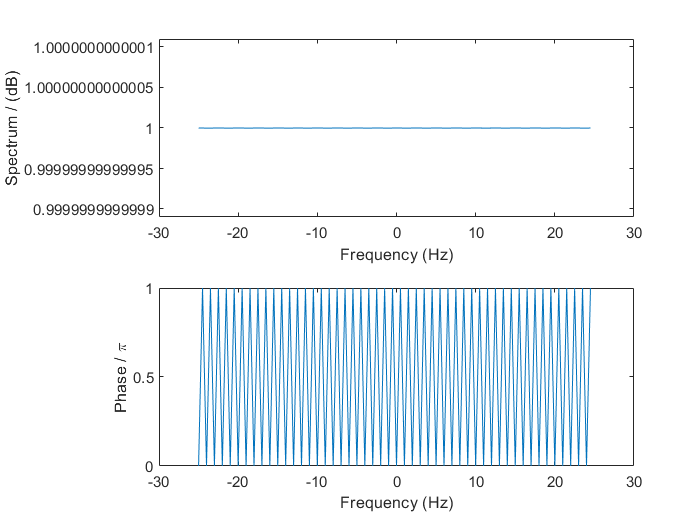

tstart = -1;
tend = 1;
fs = 50;

ts = 1/fs;
t = tstart:ts:tend-ts;
N = length(t);
x6 = zeros(1,N);
x6(t == 0) = 1;

tol = 1e-10;
f = -fs/2:fs/N:fs/2 - fs/N;
xhat = fftshift(fft(x6));
xhat = xhat / max(abs(xhat));
xhat(abs(xhat) < tol) = 0;
xhat(imag(xhat) < tol) = real(xhat(imag(xhat) < tol));

subplot(2,1,1)
plot(f, abs(xhat))
xlabel('Frequency (Hz)')
ylabel('Spectrum / (dB)')

subplot(2,1,2)
plot(f, angle(xhat) / pi)
xlabel('Frequency (Hz)')
ylabel('Phase / \pi')

theoretical fourier transform:


$$\delta \left(t\right)\longrightarrow 1$$


we can see that spectrum plot shows as same as theory says, but honestly I have no idea about phase plot!

#### x7(t)

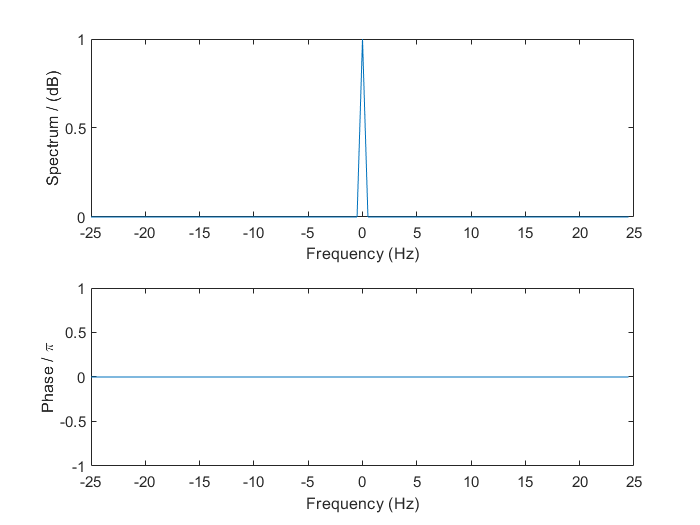

tstart = -1;
tend = 1;
fs = 50;

ts = 1/fs;
t = tstart:ts:tend-ts;
N = length(t);
x7 = ones(1,N);

f = -fs/2:fs/N:fs/2 - fs/N;
xhat = fftshift(fft(x7));
xhat = xhat / max(abs(xhat));


subplot(2,1,1)
plot(f, real(xhat))
xlabel('Frequency (Hz)')
ylabel('Spectrum / (dB)')

subplot(2,1,2)
plot(f, angle(xhat) / pi)
xlabel('Frequency (Hz)')
ylabel('Phase / \pi')

theoretical fourier transform:


$$1\longrightarrow 2\pi \delta \left(w\right)$$


As we expected, plot shows that for showing constant-time signal ($f\left(t\right)=1$) in fourier space, we only need an impulse (dirac delta) in frequency equal to zero.

### dive deeper

#### Q 1

syms t;
f = exp(-(t^2 / 8))

$$f = {\mathrm{e}}^{-\frac{t^{2}}{8}}$$

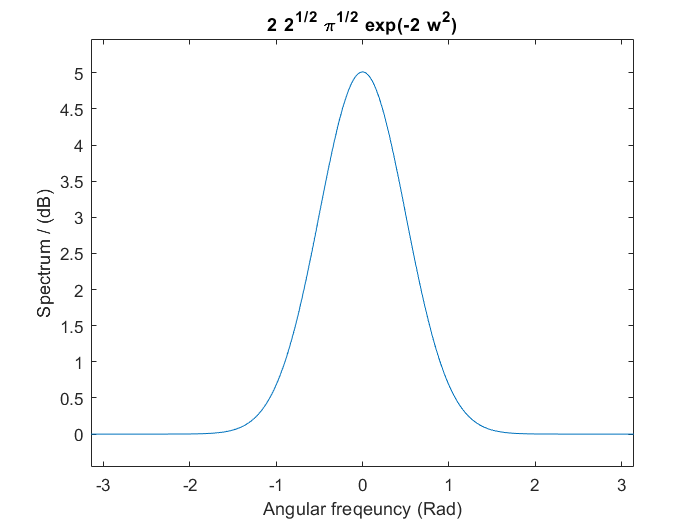

TF_f = fourier(f);
subplot(1,1,1)
ezplot(TF_f, [-pi,pi])
xlabel('Angular freqeuncy (Rad)')
ylabel('Spectrum / (dB)')

#### Q 2

Note : Based on professor live class, the new signal is:


$$x_9 \left(t\right)=\sin \left(10\pi t\right)$$


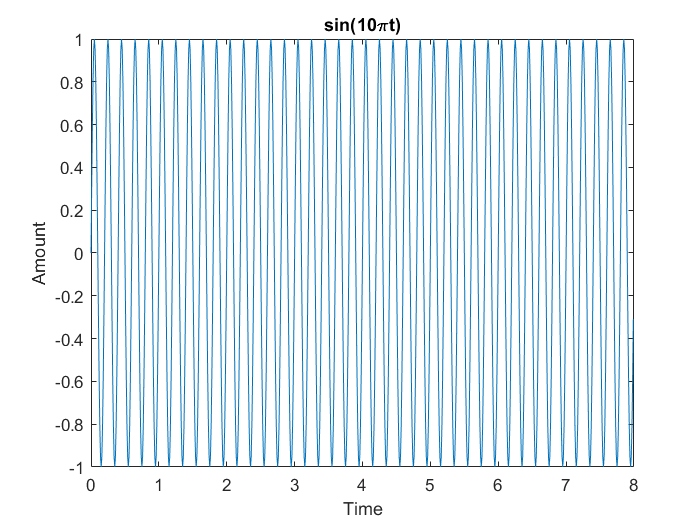

tstart = 0;
tend = 8;
ts = 0.01;
t = tstart:ts:tend-ts;
N = length(t);

x9 = sin(10 * pi * t);
subplot(1,1,1)
plot(t,x9)
xlabel('Time')
ylabel('Amount')
title('sin(10\pit)')

Fourier synthesis equation :


$$\hat{\;x_{t_s } } \left(w\right)=\sum_{m=\left(-\infty ,+\infty \right)} \;x\left(m\;t_s \right)\;e^{-j\;w\;m\;t_s }$$


Since we have finite signal, we only go form $m=t_{\mathrm{start}}$ to $m=t_{\mathrm{end}} -t_s$ 

Also we know that $w=2\pi f$; So we construct appropriate $w$ vector for our frequency vector.

fs = 1 / ts;
f = -fs/2:fs/N:fs/2 - fs/N;
w = f * 2 * pi;

Now we construct $e^{-j\;w\;m\;t_s }$ matrix which rows are different values of *m* and cols are different values of *w*

base_signals = zeros(N, length(w));
w_m_values = (t.' * w) .* -j;
base_signals = exp(w_m_values);

Now we compute Transform fourier in a super fast way!! :

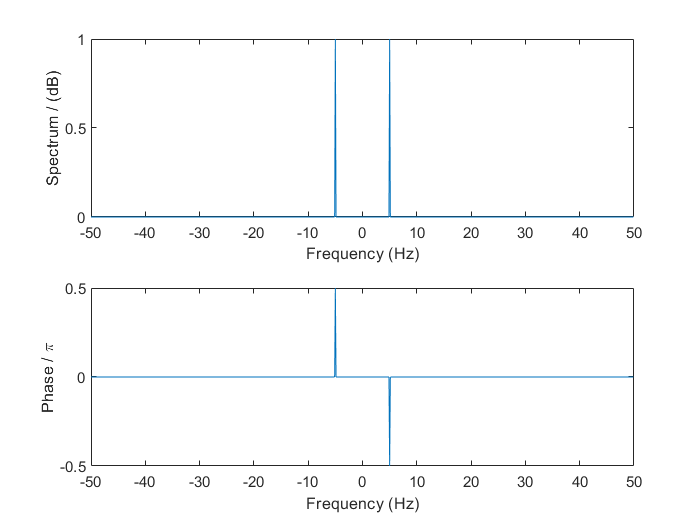

tol = 1e-6;
xhat = x9 * base_signals;
xhat = xhat / max(abs(xhat));
xhat(abs(xhat) < tol) = 0;

subplot(2,1,1)
plot(f, abs(xhat))
xlabel('Frequency (Hz)')
ylabel('Spectrum / (dB)')

subplot(2,1,2)
plot(f, angle(xhat) / pi)
xlabel('Frequency (Hz)')
ylabel('Phase / \pi')

The result is perfectly fine (I'm not gonna compare it to theoretical fourier transform cause it is ridiculously obvious).